# Analysis of Cooling within a semi-infinite glass cylinder (practice)

## Material Parameters:

% Density
rho = 2500

rho = 2500

% Heat capacity
c = 792

c = 792

% Conductivity
k = 10000

k = 10000

## Size Paramters:

dia = 5

dia = 5

nodes = 10

nodes = 10


delta_x = (dia/2) / nodes

delta_x = 0.2500

## Modelling parameters:

h = 1000

h = 1000


T_start = 900

T_start = 900

T_inf = 20

T_inf = 20

t_max = 600

t_max = 600

t_steps = 10000

t_steps = 10000


delta_t = t_max/t_steps

delta_t = 0.0600

## Computation

data = T_start * ones(1,nodes)

data =    900   900   900   900   900   900   900   900   900   900



for i = 2:t_steps
    new_row = zeros(1,nodes);
    new_row(1) = centreHT(data(i-1, 1),data(i-1,2),rho, c, k, delta_x, delta_t);
    for node = 2:(length(new_row) - 1)
        new_row(node) = internalHT(data(i-1, node), data(i-1, node-1), data(i-1, node+1), rho, c, k, delta_x, delta_t);
    end
    new_row(end) = surfaceHT(data(i-1, end), data(i-1, end-1), T_inf, rho, c, k, h, delta_x, delta_t);

    data = [data; new_row];
end

## Plot

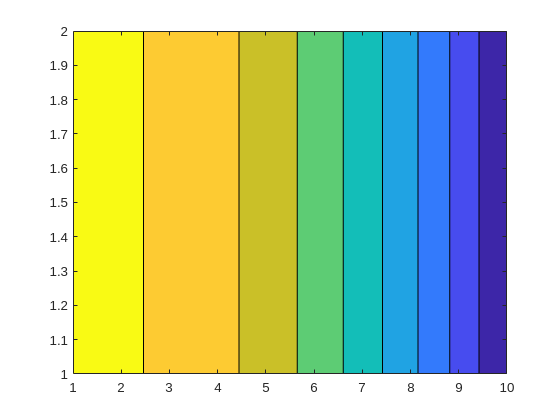

contourf([data(end,:); data(end,:)], 1:10:1000)